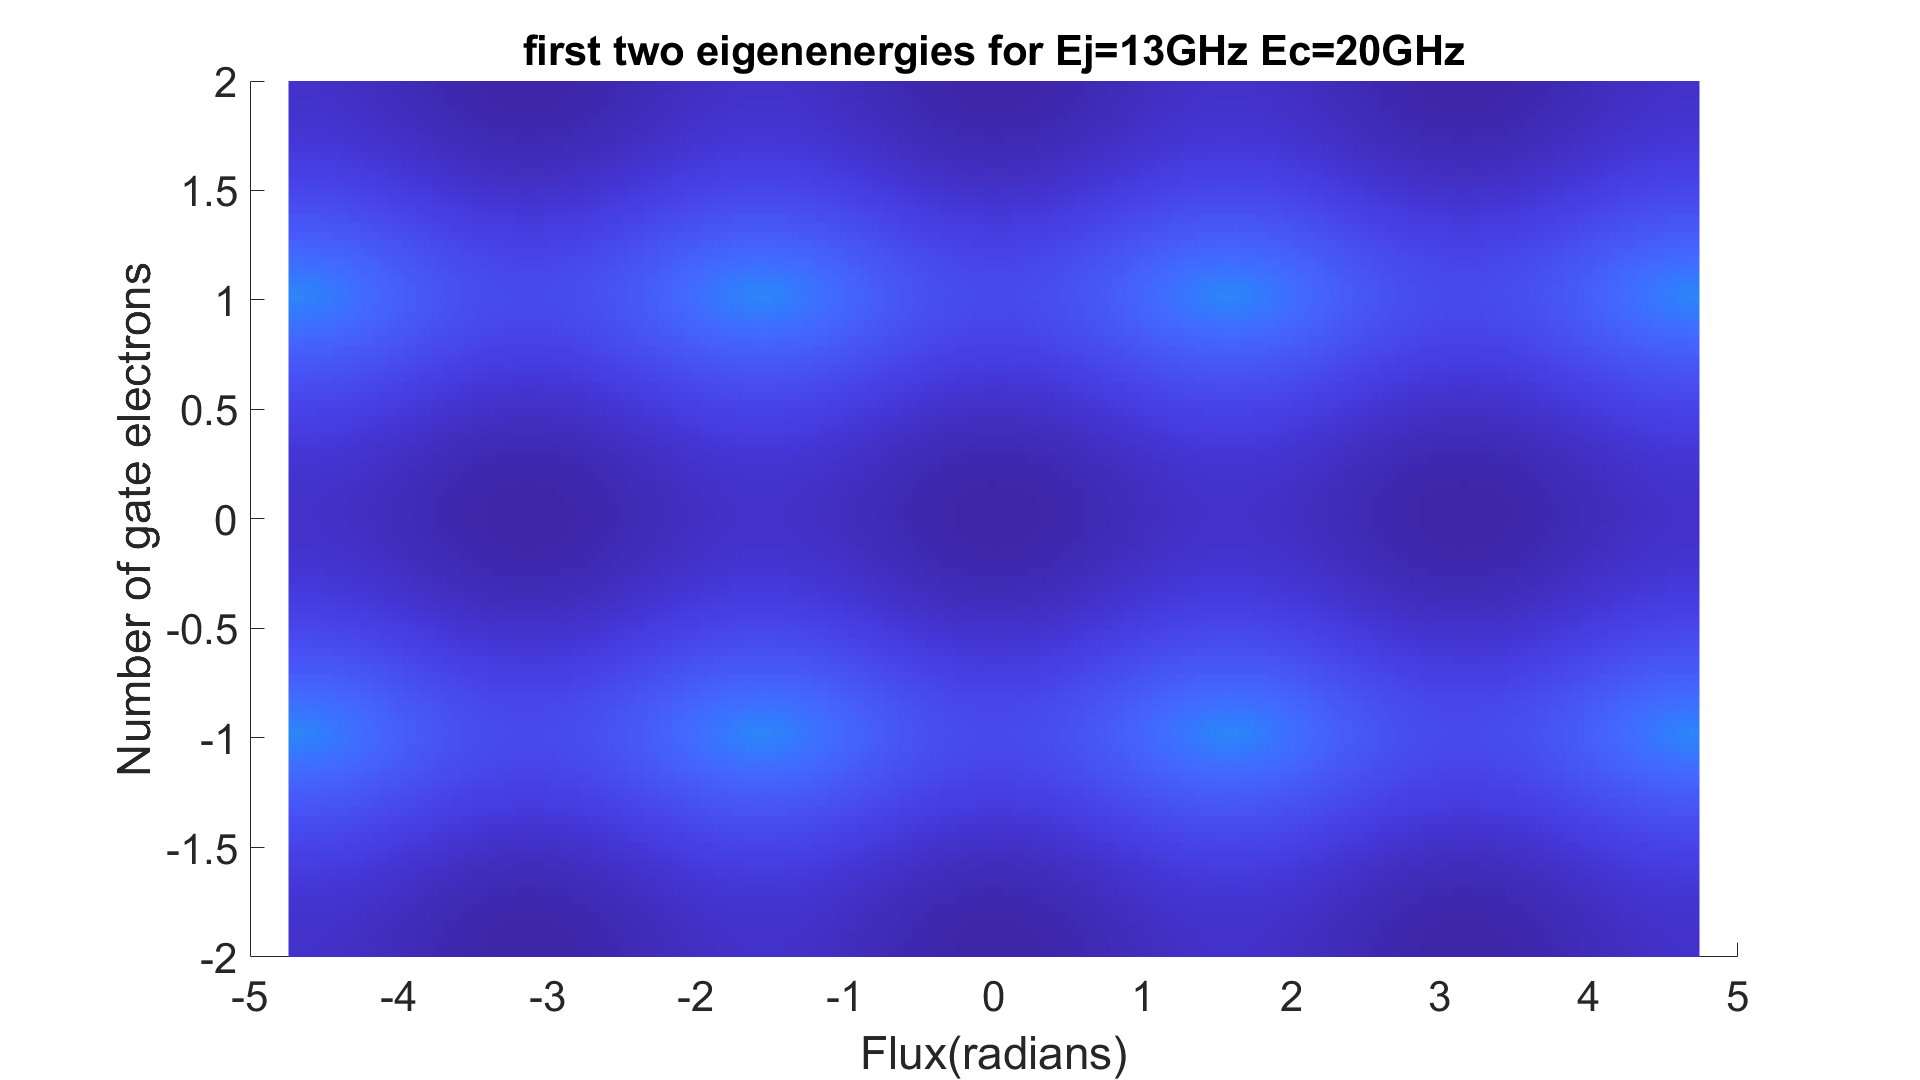

flux_period = 1109.6;
gate_period=51.2859;
Ej=13e9;
Ec=20e9;
h=6.626e-34;
e_charge=1.6e-19;
charge_states=9;
number_points=6;
if number_points>11
    disp('error')
    return
end
% Ej=Ej*Ec;
    E1=[];
    dE1=[];
    flux=[];
    gate=[];
    dE1squared=[];  
    dE1cubed=[];
    dE1fourth=[];
    freq_shift=[];
    E2=[];
    a=[];
    b=[];
    flux_values_1=[];
    gate_values_1=[];
 
a=linspace(-3*pi/2,3*pi/2,100);
b=linspace(-2,2,100);
gate_values_1=b;
flux_values_1=a;

 %%%%%  decides whether to plot eigenenergies or not %%%%%%%%%%%
    if ~exist('plot_display','var')
        plot_display=1;
    end
   
 %%%%%%%%%%%% always need an odd number of states to make it symmetric
 %%%%%%%%%%%% about 0 %%%%%%%%%%%%%%%
    if mod(charge_states,2)==0
        charge_states=charge_states+1;
    end
 %%%%%%%%% generate gate and flux values from experimental values %%%%%%%%
    delta_0=0.088;
    gate_spacing=diff(gate_values_1);
    if ~mean(gate_spacing)==gate_spacing(1)
        return
    end
    gate_spacing=gate_spacing(1);
    flux_spacing=diff(flux_values_1);
    if ~mean(flux_spacing)==flux_spacing(1)
        return
    end
    flux_spacing=flux_spacing(1);
    gate=[];
    flux=[];
    flux_spacing=flux_spacing(1);
%     for i=1:length(gate_values_1)
%         gate_temp=linspace(gate_values_1(i)-number_points*gate_spacing/20,gate_values_1(i)+number_points*gate_spacing/20,2*number_points+1);
%         gate=[gate,gate_temp];
%     end
    gate=gate_values_1;
    for i=1:length(flux_values_1)
        flux_temp=linspace(flux_values_1(i)-number_points*flux_spacing/20,flux_values_1(i)+number_points*flux_spacing/20,2*number_points+1);
        flux=[flux,flux_temp];
    end
%     for i=1:length(gate_values_1)-1
%         gate_temp=linspace(gate_values_1(i),gate_values_1(i+1),6);
%         gate_temp=gate_temp(1:end-1);
%         gate=[gate,gate_temp];
%     end
%     gate_positive=gate(gate>0);
%     c=length(gate_positive);
%     gate_negative=gate(gate<0);
%     d=length(gate_negative);
%     gate=[gate_negative+gate(1),gate,gate_positive+gate(end)];
%     gate_temp=linspace(gate_values(1)-3*gate_spacing,gate_values(1),4);
%     gate_temp=gate_temp(1:end-1);
%     gate=[gate_temp,gate];
%     gate_temp=linspace(gate_values(end),gate_values(end)+8*gate_spacing,9);
%     gate=[gate,gate_temp];
%     for i=1:length(flux_values_1)-1
%         flux_temp=linspace(flux_values_1(i),flux_values_1(i+1),6);
%         flux_temp=flux_temp(1:end-1);
%         flux=[flux,flux_temp];
%     end
%     flux_temp=linspace(flux_values(1)-3*flux_spacing,flux_values(1),4);
%     flux_temp=flux_temp(1:end-1);
%     flux=[flux_temp,flux];
%     flux_temp=linspace(flux_values(end),flux_values(end)+8*flux_spacing,9);
%     flux=[flux,flux_temp]
%     flux_positive=flux(flux>0);
%     a=length(flux_positive);
%     flux_negative=flux(flux<0);
%     b=length(flux_negative);
%     flux=[flux_negative+flux(1),flux,flux_positive+flux(end)];
%     figure
%     plot(flux)
%     title('flux values')
%     figure
%     plot(gate)
%     title('gate values')
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
 

   %%%%%%%%%%% generate the Hamiltonian matrix - charge and Josehpson
    %%%%%%%%%%% separately %%%%%%%%%%
%     v=-(charge_states-1)/2:1:(charge_states-1)/2;
%     charge=ones(charge_states,charge_states,length(gate));
%     josephson=ones(charge_states,charge_states,length(flux));
%     for i=1:length(gate)
%         for j=1:length(flux)
%             charge(:,:,i)=diag(v-gate(i)/2);
%             charge(:,:,i)=charge(:,:,i).^2;
% 
%             u=ones(length(diag(josephson(:,:,j),1)),1);
%             u=-Ej*cos(flux(j)).*u;
%             josephson(:,:,j)=diag(u,1)+diag(u,-1);
%         end
%     end
%     charge=4*Ec*repmat(charge,[1 1 1 length(flux) ]);
%     charge=permute(charge,[1 2 4 3]);
%     size(charge);
%     josephson=repmat(josephson,[1 1 1 length(gate)]);
%     size(josephson);
%     H=charge+josephson;
%     size(H);
%     for i=1:length(gate)
%         for j=1:length(flux)
%             eigenvalue(:,j,i)=eig(H(:,:,j,i));
%             E1(j,i)=eigenvalue(1,j,i);
%             E2(j,i)=eigenvalue(2,j,i);
%         end
%     end
     v=-(charge_states-1)/2:1:(charge_states-1)/2;
     charge=ones(charge_states,charge_states);
     josephson=ones(charge_states,charge_states);
     for i=1:length(gate)
         for j=1:length(flux)
             charge(:,:)=diag(v-gate(i)/2);
             charge(:,:)=4*Ec*charge(:,:).^2;
             
             u=ones(length(diag(josephson(:,:),1)),1);
             u=-Ej*cos(flux(j)).*u;
             josephson(:,:)=diag(u,1)+diag(u,-1);
             
             H=charge+josephson;
             
             eigenvalue(:,j,i)=eig(H);
             E1(j,i)=eigenvalue(1,j,i);
             E2(j,i)=eigenvalue(2,j,i);
         end
     end
    %%%%%%%%%%%%%%%%%%%%%%%%%%


     %%%%%%%%%%%%%% plot eigenenergies if needed %%%%%%%%%%%%%%
    if plot_display==1
        figure
        hold on
        q=surf(gate,flux,E1*h/e_charge/1e-6);
        xlabel('Number of gate electrons');
        ylabel('Flux(radians)');
        zlabel('E');
        set(q,'LineStyle','none');
        w=surf(gate,flux,E2*h/e_charge*1e6);
        view(90,270);
        tit=['first two eigenenergies for Ej=' num2str(Ej/1e9) 'GHz Ec=' num2str(Ec/1e9) 'GHz'];
        title(tit);
        set(w,'LineStyle','none'); 
        hold off
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

number_gate_points_for_half_period=length(gate)/(gate(end)-gate(1))

number_gate_points_for_half_period = 25

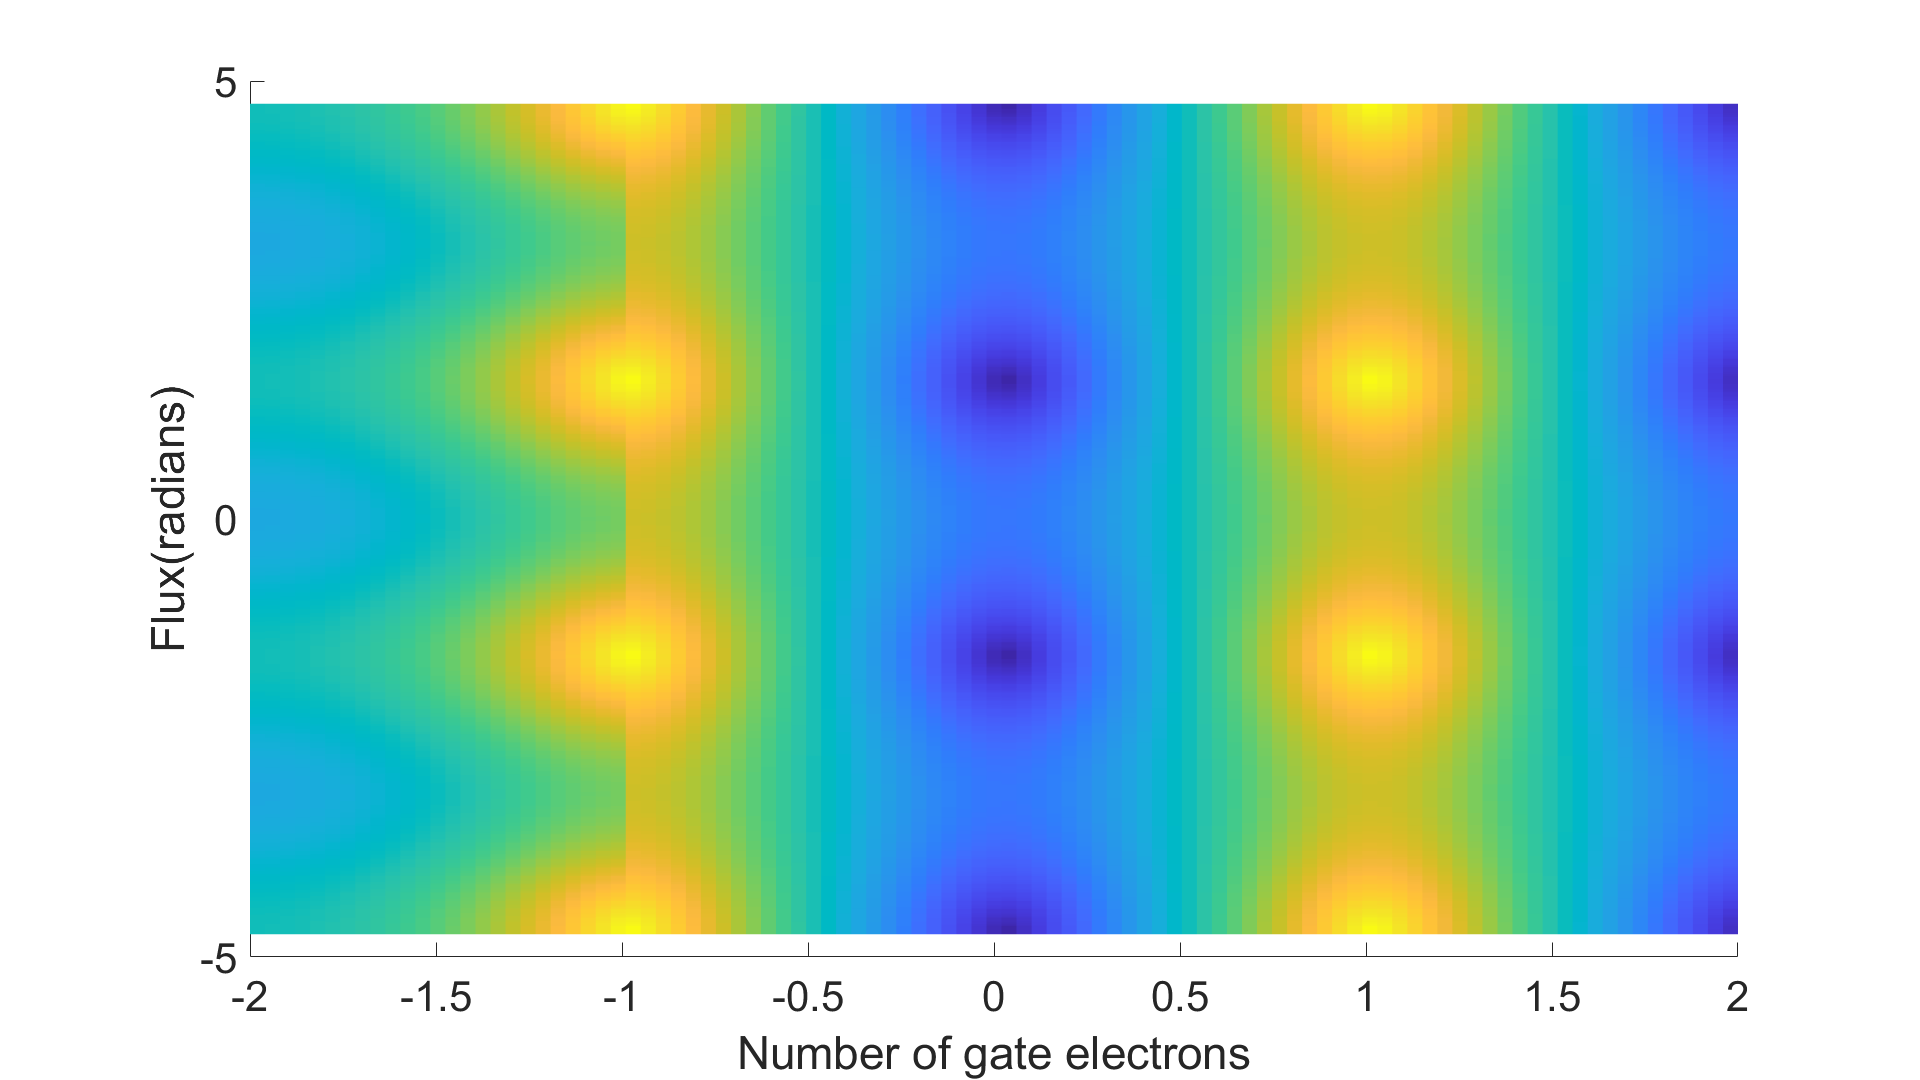

offset_E1_values=[zeros(number_gate_points_for_half_period,length(flux))' E1];
offset_E1_values=offset_E1_values(:,1:end-number_gate_points_for_half_period);

dE1=E1-offset_E1_values; % energy difference between ng = ng_0 and ng = ng_0 + 1
figure
hold on
r=surf(gate,flux,dE1*h/e_charge/1e-6);
xlabel('Number of gate electrons');
ylabel('Flux(radians)');
zlabel('E(ng=0)-E(ng=1)');
set(r,'LineStyle','none');